# Estimation of elastic properties of H313_HTI sample

**Author**: Abakumov Ivan, Martin Rühlmann

**Publication date**: 25th October 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Upload measurements on H313_HTI sample 

AlfaP = 0:5:365; 
AlfaS = 90:5:455; 

Data = zeros(2,3,length(AlfaP),10000);

for i = 1:2  % P or S wave
    for j = 1:3  % 3 independent measurements
        for k = 1:length(AlfaP)
            ii = (k-1)*6 + (j-1)*2 + i;  
            filename = ['/remote/data/ivan/Ultrasonic_data/H313_HTI/org/tek' mynum2str(ii,4) 'CH2.csv'];
            data = read_csv_files(filename,15,10014);
            Data(i,j,k,:) = data(:,2);
            tt = data(:,1);
        end
    end
end

take average among 3 observations

PData = squeeze(Data(1,:,:,:));
SData = squeeze(Data(2,:,:,:));
mPData = squeeze(mean(PData));
mSData = squeeze(mean(SData));

Amplitude normalization

nPData = mPData; 
nSData = mSData; 
for i = 1:length(AlfaP)
    nPData(i,:) = mPData(i,:)/max(mPData(i,:)); 
    nSData(i,:) = mSData(i,:)/max(mSData(i,:)); 
end

Clip first arrival signal

cPData = zeros(size(nPData)); 

for i = 1:length(AlfaP)
    trace = nPData(i,:);
    [~,imax] = max(trace);
    [~,imin] = min(trace);
    indc = round((imax+imin)/2);
    ind = (indc-200):(indc+200);
    cPData(i,ind) = nPData(i,ind)-0.01; 
end

## Find timeshifts

DT = zeros(length(AlfaP),1);
CC = zeros(length(AlfaP),1);
dt = tt(2)-tt(1);

Find timeshifts between the reference trace and all other traces

for i = 1:length(AlfaP)

        trace_ref = squeeze(cPData(1,:));
        trace = squeeze(cPData(i,:));
        [DT(i),CC(i)] = mycorr_hilbert(trace_ref, trace, dt);
end

Find absolute traveltiems

Tref = 9.47e-6; % sec
Tcor = 0.75e-6; % sec

TT = DT + Tref;

Make traveltime correction

TT = TT - Tcor;

Length of the sample 50 mm

L = 0.050;

Find phase velocities:

V = L./(TT);
V = V/1000; % (convert to km/s)

Plot the results:

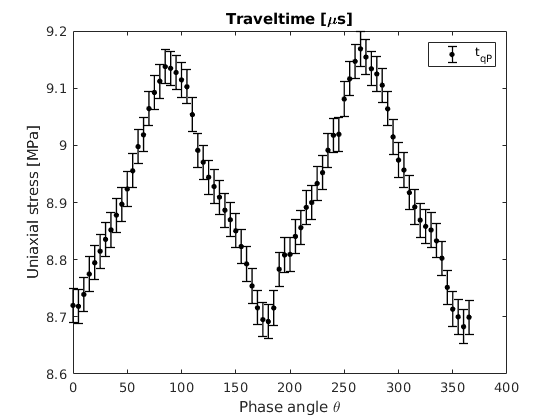

figure(121)
x_data = AlfaP;
y_data = TT'*1e6;
err_data = (0.03)*ones(size(y_data));
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on
l= legend('t_{qP}');
title('Traveltime [\mus]')
ylabel('Uniaxial stress [MPa]')
xlabel('Phase angle \theta')

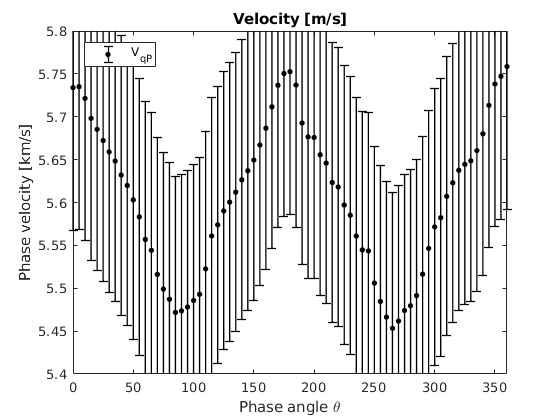



figure(122)
x_data = AlfaP;
y_data = V;
err_data = V*0.029;
errorbar(x_data,y_data,err_data,'.', 'Color','black','LineWidth',1,'MarkerSize',12);
hold on
l= legend('V_{qP}');
l.Location = 'northwest';
axis([0 360 5.4 5.8])
title('Velocity [m/s]')
xlabel('Phase angle \theta')
ylabel('Phase velocity [km/s]')


Sample.Theta  = AlfaP';     % beta  [DEG] Grad
Sample.Vp33 = min(V)*ones(size(V));       % P-velocity in vertikaler (axial) "slow"
Sample.Vp11 = max(V)*ones(size(V));       % P-velocity horizontal (radial) "fast"
Sample.Vs31 = Sample.Vp33/1.7;% S-velocity vertical  (axial) "slow"
Sample.Vs21 = Sample.Vp11/1.7;% S-velocity horizontal  (radial) "fast"
Sample.Vqp = V;
Sample.rho = 2.655;

save('/remote/data/ivan/Ultrasonic_data/H313_HTI/Sample_H313_HTI_data.mat','Sample')